Ta = 0.001;

3

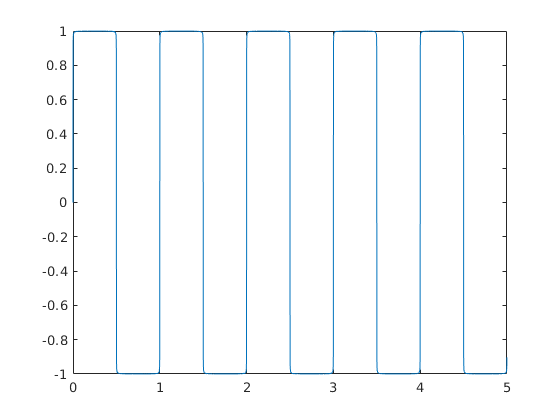

f0 = 1;
Np = 5;
k = 1:1000;
bk = (-4*(cos(pi.*k)-1))./(2*pi.*k);
ak = zeros(1,length(k));
t = 0:Ta:((Np/f0)-Ta);
x = fourierr(Ta,f0,Np,ak,bk);
figure(1)
plot(t,x)

4

Sinal Periodico Impar

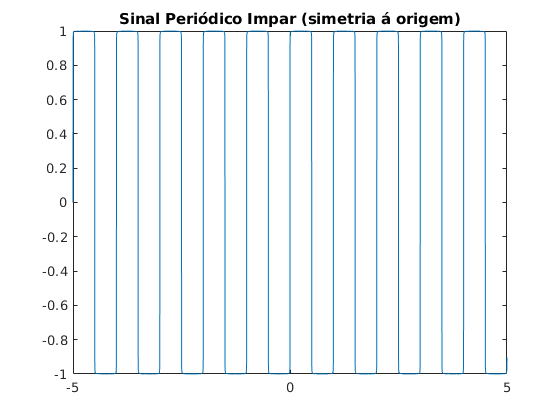

figure(2)
plot([flip(-t) t],[x x])
title("Sinal Periódico Impar (simetria á origem)")

Sinal Periodico Par

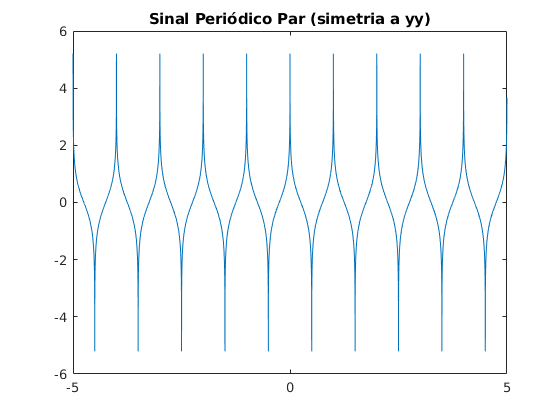

ak = bk;
bk = zeros(1,length(k));
y = fourierr(Ta,f0,Np,ak,bk);
figure(3)
plot([flip(-t) t],[y y])
title("Sinal Periódico Par (simetria a yy)")

6

exemplo)

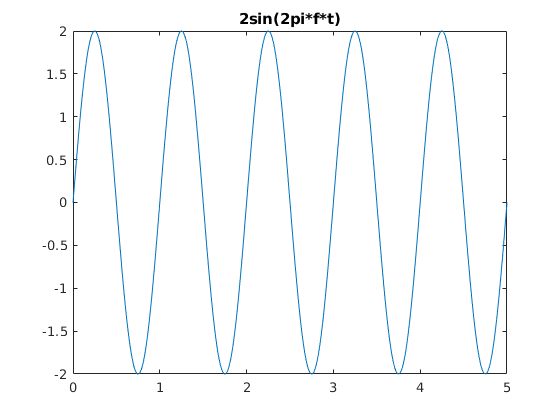

f0 = 1; T0 = 1/f0;
t = 0:Ta:5;
z = 2*sin(2*pi*f0*t);
figure(4)
plot(t,z)
title("2sin(2pi*f*t)")

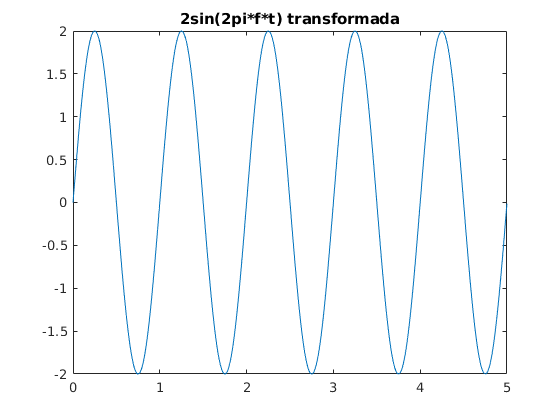

[ak,bk] = invFourier(Ta,T0,z,10);
w = fourierr(Ta,f0,5,ak,bk);
t = 0:Ta:(5*T0)-Ta;
figure(5)
plot(t,w);
title("2sin(2pi*f*t) transformada")

a)

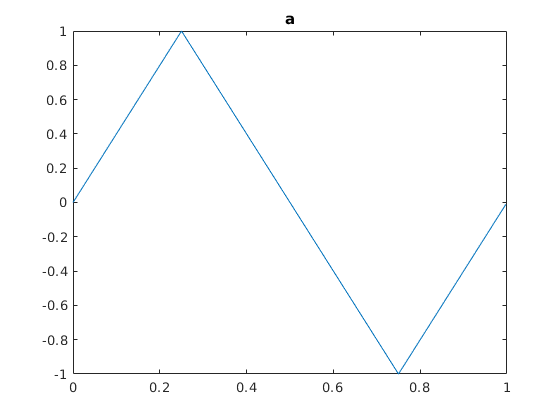

f0 = 1; T0 = 1/f0;
N = 100;
a = [0:N-1 N:-1:1-N -N:-1]/N;
Ta = 1/400;
t = (0:4*N-1)*Ta;
figure(4)
plot(t,a)
title("a")

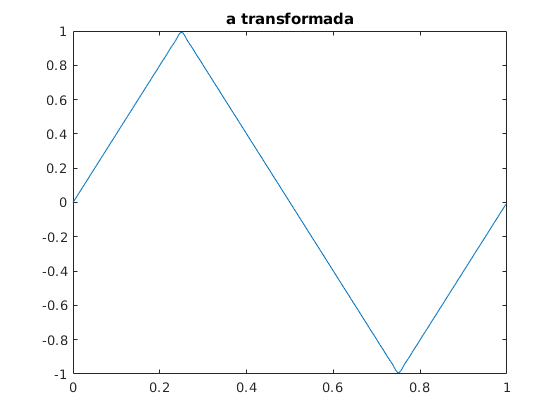

[ak,bk] = invFourier(Ta,T0,a,50);
Np = 1;
b = fourierr(Ta,f0,Np,ak,bk);
t = 0:Ta:(Np*T0)-Ta;
figure(5)
plot(t,b);
title("a transformada")

Funções

function x = fourierr(Ta,f0,Np,ak,bk)
    T0 = 1/f0;
    n = T0/Ta;
    N = Np*n;
    t = (0:N-1)*Ta;
    x = zeros(1,N);
    for k = 1:length(ak)
        x = x + ak(k)*cos(k*2*pi*f0*t);
    end
    for k = 1:length(bk)
        x = x + bk(k)*sin(k*2*pi*f0*t);
    end
end

function [ak, bk] = invFourier(Ta,T0,x,K)
    f0 = 1/T0;
    t = 0:Ta:T0-Ta;
    y = x(1:length(t));
    ak = zeros(1,K);
    bk = zeros(1,K);
    for k = 1:K
        ak(k) = 2*f0*sum(y.*cos(2*pi*f0*k*t))*Ta;
        bk(k) = 2*f0*sum(y.*sin(2*pi*f0*k*t))*Ta;
    end
end